# ECSE 343:Assignment 4

Name: Chenyi Xu

Student Id: 260948311

Due Date: 13 April 2023

## Question 1 :  

a. Write a steepest descent algorithm to solve a linear system  $\textbf A \textbf x = \textbf b$,  where $\textbf A \in \mathbb{R}^{n \times n}$ is a symmetric and positive deifnite matrix, $\textbf b \in \mathbb{R}^{n \times 1}$ and $\textbf x \in \mathbb{R}^{n \times 1}$. You can use the stencil of a function provided in the appendix. (10 marks)

% Write your code in the appendix.

b. Given a linear system  $\textbf A \textbf x = \textbf b$, where $A=\;\left\lbrack \begin{array}{ccc}
10 & 5 & 2\\
5 & 3 & 2\\
2 & 2 & 3
\end{array}\right\rbrack$.  $\textbf A$ is a symmeteric and positive definite matrix. The vector b is given as follows,  $\mathit{\mathbf{b}}=\left\lbrack \begin{array}{c}
2\\
5\\
9
\end{array}\right\rbrack$.

Solve the above system using the steepest descent method your wrote in part a.  In order to validate your answer you can use the LU decomposition method.   (2 marks)

A = [10 5 2;  5 3 2; 2 2 3];
b =[2 5 9]';

% lets also measure  the time taken by each method. This can be done by
% using the tic-toc method. You can see the details of this methods in
% MATLAB documents. We are doing it here to  demonstrate the tic-toc method
% below.

tstart_sd = tic;  % start measuring the time 
[x_sd, iter] = my_steepest_descent(A, b, zeros(3,1), 1e-6, 1000);
time_taken_sd = toc(tstart_sd);  % measure the total time taken by steepest descent method 

tstart_lu = tic;  % start measuring the time 
[L, U,P] = lu(A);
y = (L\(P*b)); %  forward substitution
x_lu = U\y;  % backward substitution
time_taken_lu = toc(tstart_lu);  % measure the total time taken by LU dec


% check the difference between the solution found by  LU decomposition + Forward/Backward Sub
% and  the steepest descent
difference = x_lu -x_sd

difference = 1.0e-05 *

   -0.3242
    0.7747
   -0.3040


norm_difference = norm(difference)

norm_difference = 8.9314e-06

c. In this question, you will solve the matrix systems of size ranging for n= 2, 3, 4 , 5, ..., 100 .  Use the function named *getSystemMatrix_with_lowerConditionNumber* (provided in the appendix) to generate the system matrix $\textbf A$ and the vector $\textbf b$ of  size n.  The matrix $\textbf A$ generated by the *getSystemMatrix_with_lowerConditionNumber.m* has a good condition number.

Use the LU decomposition based method and the steepest descent method  to compute the solution of linear system with size ranging from n =2  to 100.  Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size. On the same figure, plot the time taken by Steepest Descent method to find the solution.  Label the axes of the plot and include the legend.

Which method takes more time to compute the solution?

Use the cell below to write your code. For measuring  the time taken by each method you can use the code provided in part  b and then change it accordingly.   (8 marks)

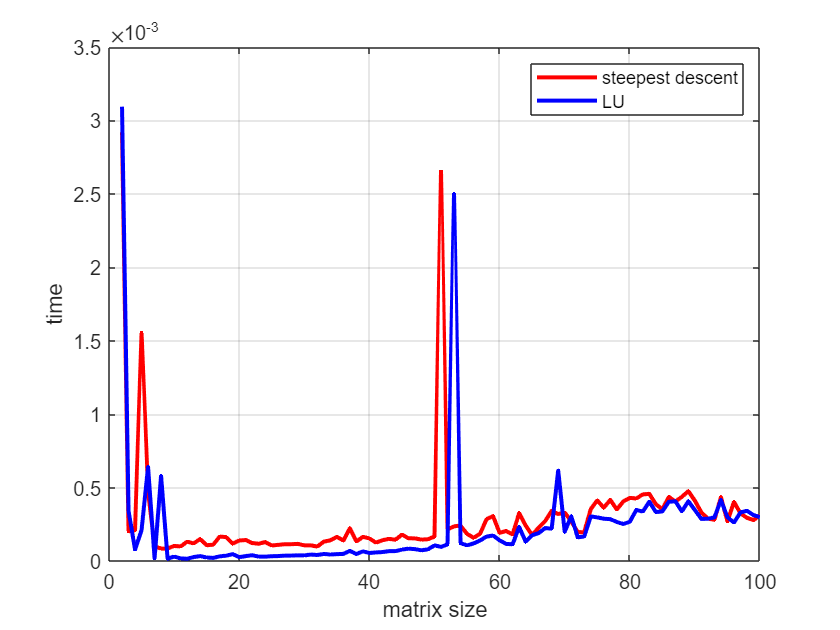

time_taken_lu = [];
time_taken_sd = [];
for n = 2 : 100
    [A , b] = getSystemMatrix_with_lowerConditionNumber(n);

    % LU method 
    tstart_lu = tic;  % start measuring the time 
    [L, U,P] = lu(A);
    y = (L\(P*b)); %  forward substitution
    x_lu = U\y;  % backward substitution
    time_taken_lu(n-1) = toc(tstart_lu);  % measure the total time taken by LU dec

    % Steepest step 
    tstart_sd = tic;  % start measuring the time 
    [x_sd, iter] = my_steepest_descent(A, b, zeros(n,1), 1e-6, 1000);
    time_taken_sd(n-1) = toc(tstart_sd);  % measure the total time taken by steepest descent method 
    
end

% Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size.
% plot the time taken by Steepest Descent method to find the solution

figure
plot(2:100, time_taken_sd, 'r-','LineWidth',2,'displayname','steepest descent')
hold on
plot(2:100, time_taken_lu, 'b-','LineWidth',2,'displayname','LU')
xlabel('matrix size')
ylabel('time')
grid on 
legend

Initially, LU method takes more time. However, as the matrix size grows, Steepest descent method takes more time to compute as reflected in the graph. 

*d. *In this part you will repeat part c,  however, this time you need to solve the matrix systems of size ranging from n= 2 to 1000.

Similar to part c, plot the time taken by LU decomposition based solver and the steepest descent for each matrix size. Make sure your plots are properly labeled. On a seperate plot also plot the number of iterations taken by steepest decent vs matrix size.

Compare the plots from part c and d, which method takes more time to compute the solution?

Use the cell below to write your code. (5 marks)

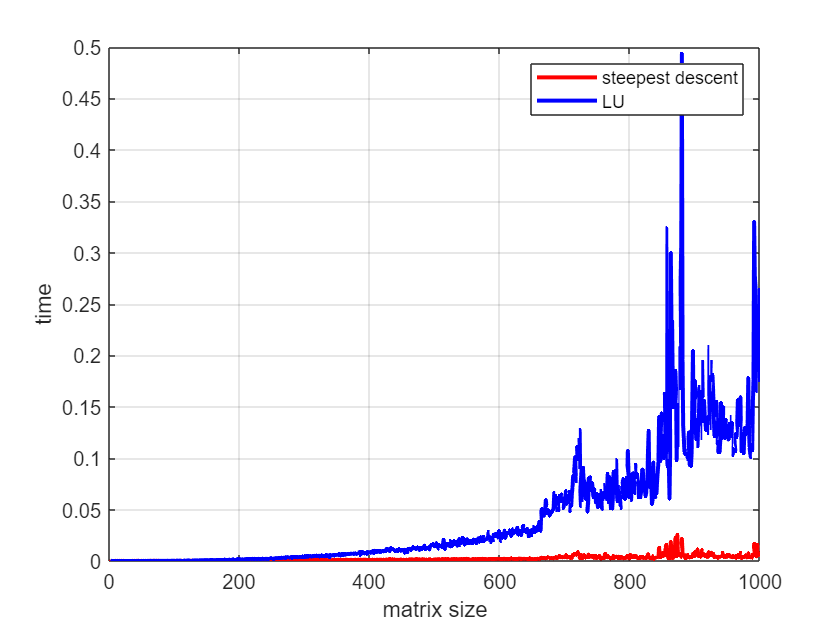

% write your code here.
clear all

time_taken_lu = [];
time_taken_sd = [];
iter_e = [];
for n = 2 : 1000
    [A , b] = getSystemMatrix_with_lowerConditionNumber(n);

    % LU method 
    tstart_lu = tic;  % start measuring the time 
    [L, U,P] = lu(A);
    y = (L\(P*b)); %  forward substitution
    x_lu = U\y;  % backward substitution
    time_taken_lu(n-1) = toc(tstart_lu);  % measure the total time taken by LU dec

    % Steepest step 
    tstart_sd = tic;  % start measuring the time 
    [x_sd, iter] = my_steepest_descent(A, b, zeros(n,1), 1e-6, 1000);
    time_taken_sd(n-1) = toc(tstart_sd);  % measure the total time taken by steepest descent method 
    iter_e(n-1) =iter;
end

% Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size.
% plot the time taken by Steepest Descent method to find the solution

figure
plot(2:1000, time_taken_sd, 'r-','LineWidth',2,'displayname','steepest descent')
hold on
plot(2:1000, time_taken_lu, 'b-','LineWidth',2,'displayname','LU')
xlabel('matrix size')
ylabel('time')
grid on 
legend

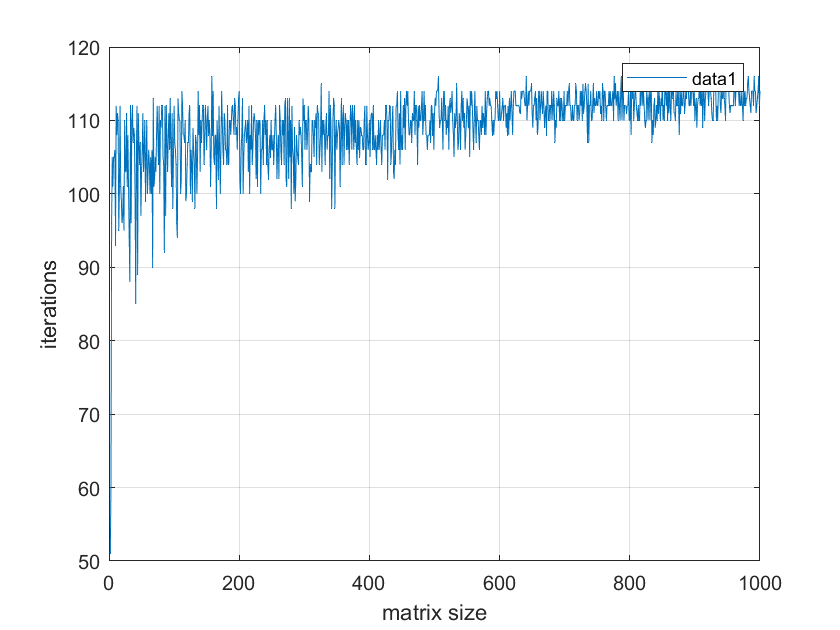


figure
plot(2:1000, iter_e)
xlabel('matrix size')
ylabel('iterations')
grid on 
legend

LU methods takes more time to compute as reflected from the graph. 

e. Similar to the previous part*, *you need to solve the matrix systems of size ranging from n= 2 to 1000.  

Instead this time you will use the function *getSystemMatrix_with_higherConditionNumber *to generate the system matrix $\textbf A$* and vector *$\textbf b$*. T*he function is provided in the appendix. The function, *getSystemMatrix_with_higherConditionNumber, * generates the system matrix $\textbf A$  which has a slightly higher condition number than the matrix you used in parts c and d.

Plot the time taken by LU  decomposition based solver and the steepest descent for each matrix size. Also plot the number of iterations taken by steepest decent vs matrix size.

Comment on the similarities and difference between the  plots from part d and e.

You can use the cell below to write your code. (5 marks)

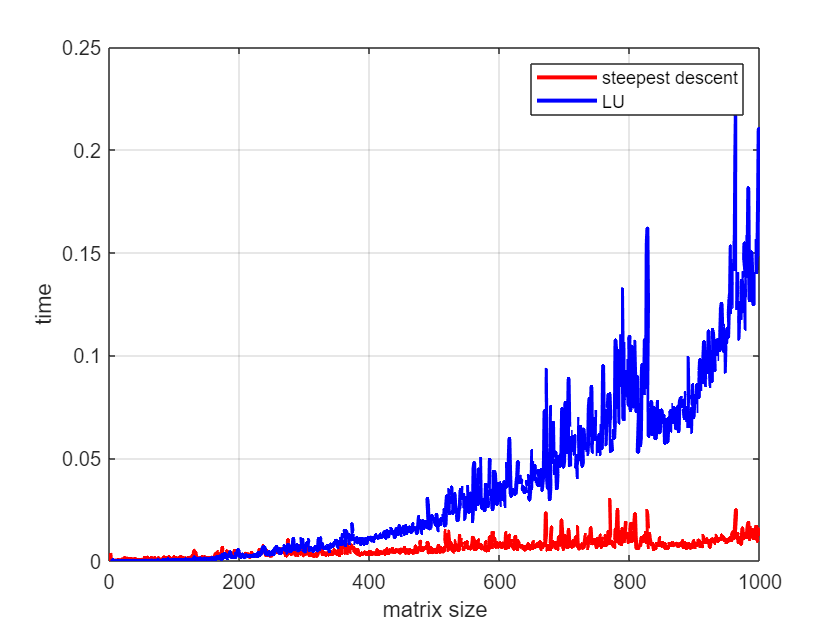

% write your code here.
clear all

time_taken_lu = [];
time_taken_sd = [];
iter_e = [];
for n = 2 : 1000
    [A , b] = getSystemMatrix_with_higherConditionNumber(n);

    % LU method 
    tstart_lu = tic;  % start measuring the time 
    [L, U,P] = lu(A);
    y = (L\(P*b)); %  forward substitution
    x_lu = U\y;  % backward substitution
    time_taken_lu(n-1) = toc(tstart_lu);  % measure the total time taken by LU dec

    % Steepest step 
    tstart_sd = tic;  % start measuring the time 
    [x_sd, iter] = my_steepest_descent(A, b, zeros(n,1), 1e-6, 1000);
    time_taken_sd(n-1) = toc(tstart_sd);  % measure the total time taken by steepest descent method 
    iter_e(n-1) = iter;
    
end

% Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size.
% plot the time taken by Steepest Descent method to find the solution

figure
plot(2:1000, time_taken_sd, 'r-','LineWidth',2,'displayname','steepest descent')
hold on
plot(2:1000, time_taken_lu, 'b-','LineWidth',2,'displayname','LU')
xlabel('matrix size')
ylabel('time')
grid on 
legend

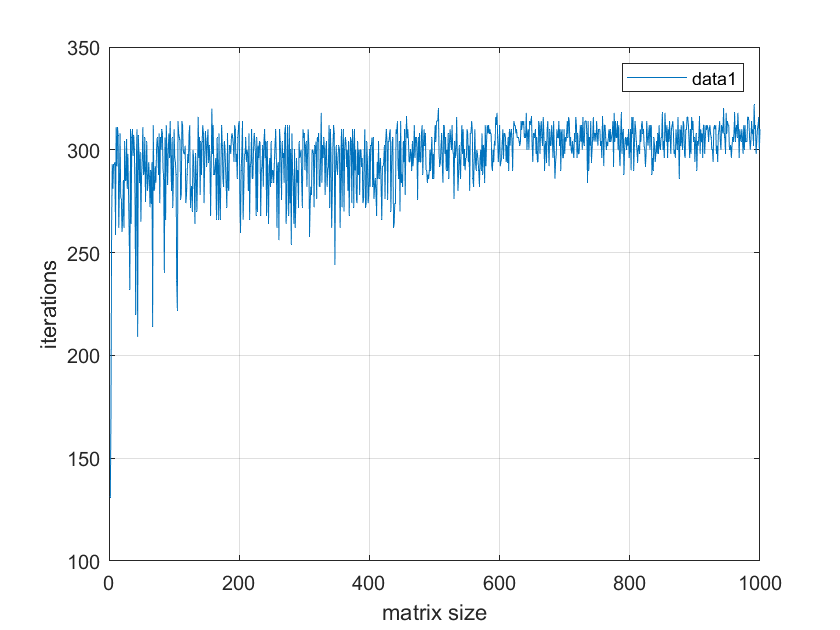


figure
plot(2:1000, iter_e)
xlabel('matrix size')
ylabel('iterations')
grid on 
legend

The graph for d and e has the same shape. For both graph, LU method has a longer run time than steeest descent method. Howver, for e the graph has slightly higher run time. e has more iterations than d as shown in the iteration graph, therefore it takes it more time to converge and therefore higher run time. 

## Appendix 

function [A,b]= getSystemMatrix_with_lowerConditionNumber(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.25);
    A= R'*R;
    b = rand(n,1);
end

function [A,b]= getSystemMatrix_with_higherConditionNumber(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.15);
    A= R'*R;
    b = rand(n,1);
end

Write your steepest descent here.

function [x, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter)
% inputs: A- a symmeteric and positiv definite matrix.
%         b : RHS vector
%        Xguess: Initial guess 
%        tol : tolerance 
%         maxiter:maximum iterations 

%outputs:  x: solution of the system Ax =b
%          iter: number of iterations it took to converge

%initialize the variables
iter = 0;
x = Xguess;
r = b - A*x;
residual_norm = norm(r);

% loop 
while residual_norm > tol && iter < maxiter
    iter = iter + 1;
    
    % step size
    step_size = (r'*r) / (r'*A*r);
    
    % update 
    x = x + step_size*r;
    
    % new 
    r = b - A*x;
    residual_norm = norm(r);
end
end